clear variables; close all; clc;

function dist_ood = calculateOOD(data, slope, const)
    dist_ood = table;
    if const
        r = repelem(slope, numel(data.y));
    else
        x = data.x;
        slope_x = x.*slope;
        r = slope * sqrt(x.^2 + slope_x.^2);
    end

    for i = 1:numel(data.x)
        dist = abs(data.y(i)) - r(i);
        if dist < 0
            dist = 0;
        end
        dist_ood.ood(i) = abs(dist);
    end
    dist_ood = [data dist_ood];
end

function data = grabData(data_g, data_c)
    data = table;
    data.error_NN_h = data_c.error_h; %NN Error, height offset 
    data.error_NN_y = data_c.error_y; %NN Error, crosstrack offset 
    data.y_pred = data_g.y_err; %NN Output- Predicted crosstrack offset 
    data.h_pred = data_g.h_err_NN; %NN Output- Predicted height offset
    data.h_true = data_g.h_err_true; %True height error based on state info 

    %True State Information 
    data.y = data_c.y;
    data.x = data_c.x; %Horizontal distance from runway 
    data.h = data_c.h; %True Height (Altitude relative to runway) 
end

slope = tand(3.5);
%Process 'super safe' data set from within 3.5deg cone
csvDataSafe_g = readtable("/media/storage_drive/ULI Datasets/dataWPI_1500_50_10/safe/2024-7-19/generated_states.csv"); %50m, OOD by 0
csvDataSafe_c = readtable("/media/storage_drive/ULI Datasets/dataWPI_1500_50_10/safe/2024-7-19/combined_states.csv");
safe_signals = readtable("/home/achadbo/XPlaneAutolandScenario/Subsets/scod_supersafe");

safe_signals = calculateOOD(safe_signals, slope, false);
safe = grabData(csvDataSafe_g, csvDataSafe_c);
safe_ood = calculateOOD(safe, slope, false);

%Process 'less safe' data set from within 10deg cone
csvDataUnsafe_g = readtable("/media/storage_drive/ULI Datasets/dataWPI_1500_50_10/unsafe/2024-7-19/generated_states.csv"); %50m, OOD by 0
csvDataUnsafe_c = readtable("/media/storage_drive/ULI Datasets/dataWPI_1500_50_10/unsafe/2024-7-19/combined_states.csv");
unsafe_signals = readtable("/home/achadbo/XPlaneAutolandScenario/Subsets/scod_unsafe");

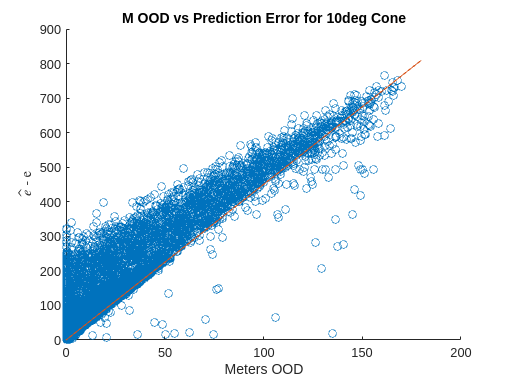

signals = calculateOOD(unsafe_signals, slope, false);
unsafe = grabData(csvDataUnsafe_g, csvDataUnsafe_c);
unsafe_ood = calculateOOD(unsafe, slope, false);
%unsafe_ood = unsafe_ood(unsafe_ood.ood > 0, :);

scatter(unsafe_ood.ood, abs(unsafe_ood.y_pred));
hold on;
%scatter(signals.signal, signals.ood);
%scatter(signals.signal * 100, abs(signals.y));
x = 0:180;
plot(x, (4.5 * x));
xlabel("Meters OOD");
ylabel('$\hat{e}$ - e','Interpreter','Latex');
title("M OOD vs Prediction Error for 10deg Cone");
hold off;

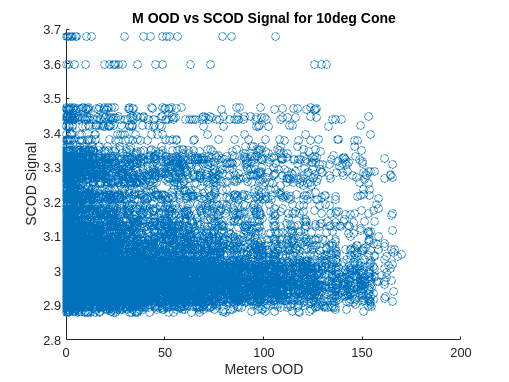


scatter(signals.ood, signals.signal);
hold on;
xlabel("Meters OOD");
ylabel("SCOD Signal");
title("M OOD vs SCOD Signal for 10deg Cone");
hold off;

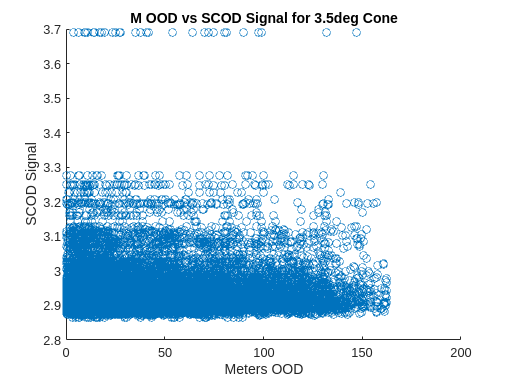


safe_signals = safe_signals(safe_signals.ood > 0, :);
scatter(safe_signals.ood, safe_signals.signal);
hold on;
xlabel("Meters OOD");
ylabel("SCOD Signal");
title("M OOD vs SCOD Signal for 3.5deg Cone");
hold off;


csv_200 = readtable("/home/achadbo/XPlaneAutolandScenario/Subsets/scod_200");

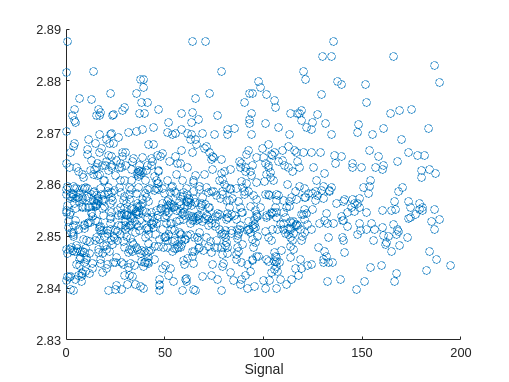

data_200 = calculateOOD(csv_200, slope, false);
data_200 = data_200(data_200.ood > 0, :);

scatter(data_200.ood, data_200.signal);
xlabel("Signal");
title("");